## In the name of Allah

## Project 4:

## Hossein Alizadeh Piralidehi 810100522

### Problem considerations:

$c_t \ge 0$ denotes the amount that the investor commits in period *t.*  

$p_t \ge 0$ denotes the amount that the investor pays in to the investment in response to capital calls in period *t*.  

$d_t \ge 0$ denotes the amount that the investor receives in distributions from the investment in period *t*.  

$n_t \ge 0$ denotes the net asset value (NAV) of the investment in period *t*.

$u_t \ge 0$ denotes the total amount of uncalled commitments, i.e., the difference between the total so far committed and the total so far that has been called (and paid into the investment).

dynamic of these varables are given:


$$n_{t+1} =\left(1+r\right)n_t +p_t -d_t \;\;\;\;\;\;\;\;\;\;u_{t+1} =u_t -p_t +c_t \;\;\;\;\;\;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T$$



$$u_1 =n_1 =0$$



$$p_t =\gamma {\;}^{\mathrm{call}} u_t \;\;\;\;\;\;\;\;d_t =\gamma {\;}^{\mathrm{dist}} n_t$$


commitements and capital calls are limited:


$$c_t \le c_{\max } \;\;\;\;\;p_t \le p_{\max } \;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T$$


we have a total budget B:


$$1^T c\le B$$


problem objective is to minimize:


$$f_0 \left(c\right)=\frac{1}{T+1}\sum_{t=1}^{T+1} {\left(n_t -n_{\mathrm{des}} \right)}^2 +\frac{\lambda }{T-1}\sum_{t=1}^{T-1} {\left(c_{t+1} -c_t \right)}^2$$


### Description:

given optimization problem is:


$$\min \;\frac{1}{T+1}\sum_{t=1}^{T+1} {\left(n_t -n_{\mathrm{des}} \right)}^2 +\frac{\lambda }{T-1}\sum_{t=1}^{T-1} {\left(c_{t+1} -c_t \right)}^2$$



$$\begin{array}{l}
s\ldotp t\ldotp \\
\;\;\;\;\;\;c_t \le c_{\max } \;\;\;\;\;\;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T\;\;\;\;\\
\;\;\;\;\;{\;c}_t \ge 0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T\\
{\;\;\;\;\;1}^T c\le B\\
\;\;\;\;\;{\;p}_t \le p_{\max } \;\;\;\;\;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T\\
\;\;\;\;\;\;p_t \ge 0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T\\
\;\;\;\;\;\;n_{t+1} =\left(1+r\right)n_t +p_t -d_t \;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T\\
\;\;\;\;\;\;u_{t+1} =u_t -p_t +c_t \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T\\
{\;\;\;\;\;\;u}_1 =n_1 =0\\
\;\;\;\;\;\;p_t =\gamma {\;}^{\mathrm{call}} u_t \;\;\;\;\;\;\;\;d_t =\gamma {\;}^{\mathrm{dist}} n_t 
\end{array}$$
 

at first we try to reduce number of variables and constraints of problem. 

**using formulas for **$u_{t+1}$** :**


$$\begin{array}{l}
\beta =1-\gamma^{\mathrm{call}} \\
u_1 =0\\
u_{t+1} =u_t -\gamma^{\mathrm{call}} u_t +c_t =\beta u_t +c_t \\
u_2 =c_1 \\
u_3 =c_2 +\beta \;c_1 \\
u_4 =c_3 +\beta c_2 +\beta^2 c_1 \\
u_5 =c_4 +\beta c_3 +\beta^2 c_2 +\beta^3 c_1 \\
\ldotp \ldotp \ldotp \\
u_{t+1} =c_t +\beta c_{t-1} +\;\ldotp \ldotp \ldotp \;+\beta^{t-2} c_2 +\beta^{t-1} c_1 
\end{array}$$


**using formula for **$n_{t+1}$**:**


$$\alpha =1+r-\gamma^{\mathrm{dist}}$$



$$\begin{array}{l}
n_1 =0\\
n_{t+1} =\left(1+r\right)n_t +\gamma^{\mathrm{call}} u_t -\gamma^{\mathrm{dist}} n_t =\alpha \;n_t +\gamma^{\mathrm{call}} u_t \\
n_2 =0\\
n_3 =\gamma^{\mathrm{call}} u_2 \\
n_4 =\gamma^{\mathrm{call}} \left(u_3 +\alpha \;u_2 \right)\\
n_5 =\gamma^{\mathrm{call}} \left(u_4 +\alpha \;u_3 +\alpha^2 \;u_2 \right)\\
\ldotp \ldotp \ldotp \\
n_{t+1} =\gamma^{\mathrm{call}} \left(u_t +\alpha u_{t-1} +\;\ldotp \ldotp \ldotp \;+\alpha^{t-2} u_2 \right)
\end{array}$$


now we replace calculated $u_t$ into $n_{t+1}$ formula:


$$\begin{array}{l}
n_1 =0\\
n_2 =0\\
n_3 =\gamma^{\mathrm{call}} c_1 \\
n_4 =\gamma^{\mathrm{call}} \left\lbrack c_2 +\left(\beta \;+\alpha \right)c_1 \right\rbrack \\
n_5 =\gamma^{\mathrm{call}} \left\lbrack c_3 +\left(\beta +\alpha \right)c_2 +\left(\beta {\;}^2 +\alpha \beta +\alpha^2 \right)c_1 \right\rbrack \\
\ldotp \ldotp \ldotp \\
n_{t+1} =\gamma^{\mathrm{call}} \left\lbrack c_{t-1} +\left(\beta +\alpha \;\right)c_{t-2} +\left(\beta {\;}^2 +\alpha \;\beta +\alpha^2 \right)c_{t-3} +\;\ldotp \ldotp \ldotp +\left(\beta {\;}^{t-2} +\beta {\;}^{t-3} \alpha +\ldotp \ldotp \ldotp +\beta \;\alpha {\;}^{t-3} +\alpha^{t-2} \right)c_1 \right\rbrack 
\end{array}$$


finally the oprimization problem will be rewritten with:


$$\begin{array}{l}
\min \;f_0 \left(c\right)\\
s\ldotp t\ldotp \\
\;\;\;\;\;n_{t+1} =\gamma^{\mathrm{call}} \left\lbrack c_{t-1} +\left(\beta +\alpha \;\right)c_{t-2} +\left(\beta {\;}^2 +\alpha \;\beta +\alpha^2 \right)c_{t-3} +\;\ldotp \ldotp \ldotp +\left(\beta {\;}^{t-2} +\beta {\;}^{t-3} \alpha +\ldotp \ldotp \ldotp +\beta \;\alpha {\;}^{t-3} +\alpha^{t-2} \right)c_1 \right\rbrack \;\;\;\;\;t=2,\ldotp \ldotp \ldotp ,T\\
\;\;\;\;\;n_1 =n_2 =0\\
\;\;\;\;\;n_t \ge 0\;\;\;t=3,\ldotp \ldotp \ldotp ,T\\
\;\;\;\;\;{0\le u}_t \le \frac{p_{\max } }{\gamma^{\mathrm{call}} }\;\;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T\\
\;\;\;\;\;0\le c_t \le c_{\max } \;\;\;\;t=1,2,\ldotp \ldotp \ldotp ,T\\
\;\;\;\;\;1^T c\le B
\end{array}$$


all of constraints are affine in $c_t$ so all of them are convex. objective is quadratic form ($c^T \mathrm{Qc}$) which $Q$ is PD, so objective is convex, finally there is convex optimization problem which can be solved using cvx toolbox.

### Simulation with given parameters:

## Part a)

load parameters

clc;clear;close all;

T = 40; r = 0.04;
gamma_call = 0.23; gamma_dist = 0.15;
c_max = 4; p_max = 3; B = 85;
n_des = 15; lambda = 5;

alpha = 1 + r - gamma_dist;
beta = 1 - gamma_call;

solve convex problem using cvx toolbox

cvx_begin
    variables c(T);
        u(2) = c(1);
        for t = 2 : T
            u(t+1) = (1-gamma_call).^(0:t-1)*c(t:-1:1);
            for i = 1 : t-1
                coeff(i) = sum(alpha.^(0:i-1) .* beta.^(i-1:-1:0));
            end
            n(t+1) = gamma_call*( coeff *c(t-1:-1:1));
        end
    minimize( 1/(T+1) * sum((n-n_des).^2) + lambda/(T-1) * sum( (c(2:end)-c(1:end-1)) .^2 ) );
    subject to
        n(1) == 0;
        n(2) == 0;
        n(:) >= 0;
        
        u(:) >= 0;
        u(:) <= p_max/gamma_call;
        
        c(:) >= 0;
        c(:) <= c_max;
        ones(1, T)*c <= B;
cvx_end

 
Calling SDPT3 4.0: 435 variables, 118 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 118
 dim. of sdp    var  = 156,   num. of sdp  blk  = 78
 dim. of linear var  = 201
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.4e+02|9.4e+00|4.2e+05| 1.325268e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.835|0.863|5.6e+01|1.3e+00|7.1e+04| 1.619579e+04 -8.711582e+01| 0:0:00| chol  1  1 
 2|0.777|0.826|1.2e+01|2.3e-01|3.1e+04| 1.741752e+04 -4.578164e+02| 0:0:00| chol  1  1 
 3|0.996|1.000|4.9e-02|1.0e-04|9

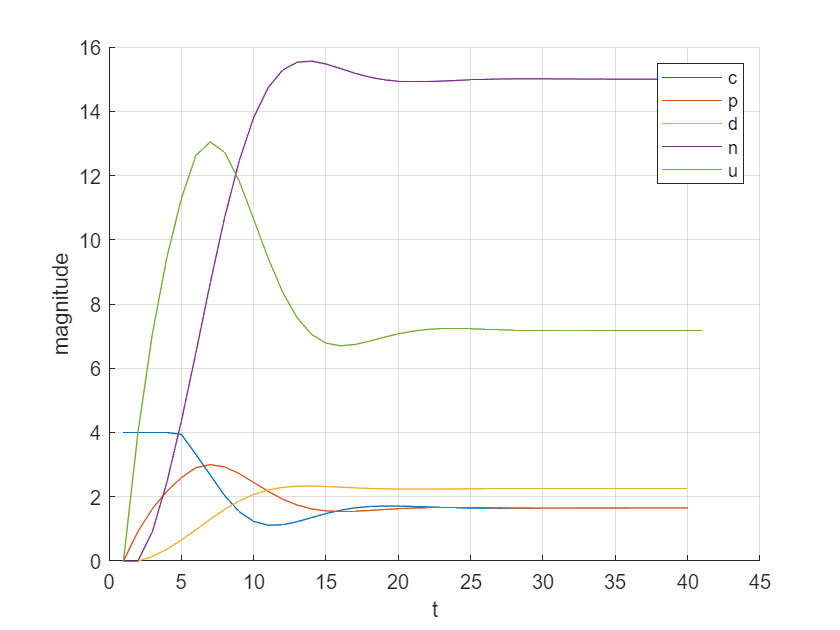

p(1:T) = gamma_call*u(1:T);
d(1:T) = gamma_dist*n(1:T);
figure
hold on
grid on
plot(c)
plot(p)
plot(d)
plot(n)
plot(u)
xlabel('t')
ylabel('magnitude')
legend('c', 'p', 'd', 'n', 'u')

disp("Objective value: " +  (1/(T+1) * sum((n-n_des).^2) + lambda/(T-1) * sum( (c(2:end)-c(1:end-1)) .^2 )) )

Objective value: 26.0552


disp("Tracking error value: " +  1/(T+1) * sum((n-n_des).^2))

Tracking error value: 25.8462


## Part b)

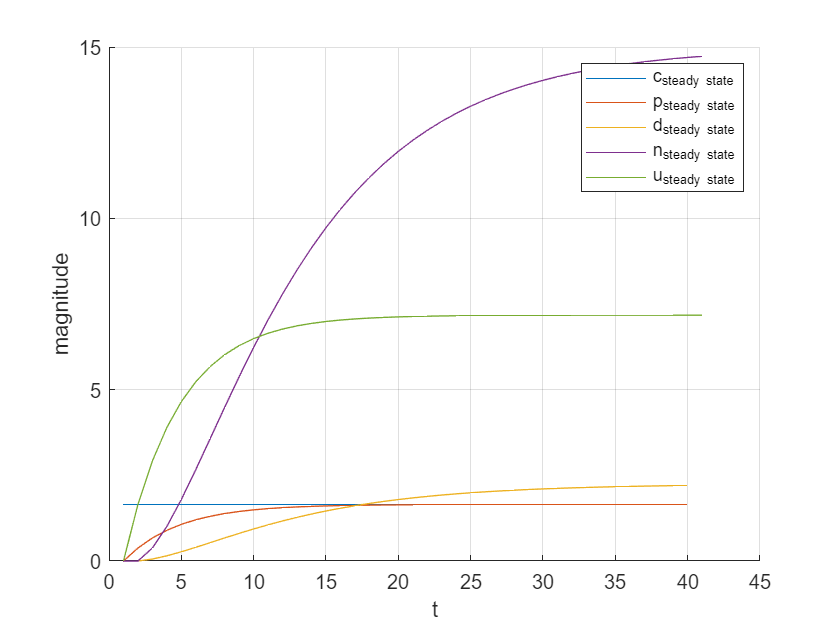

c_ss = (gamma_dist-r)*n_des*ones(T,1);
u_ss(2:T+1) = (gamma_dist-r)*n_des/(1-beta)*(1-beta.^(1:T));
n_ss = zeros(T+1,1);
for t = 2 : T
    coeff_ss = [];
    for i = 1 : t-1
        coeff_ss(i) = sum(alpha.^(0:i-1) .* beta.^(i-1:-1:0));
    end
    n_ss(t+1) = gamma_call*( coeff_ss *c_ss(t-1:-1:1));
end
p_ss(1:T) = gamma_call*u_ss(1:T);
d_ss(1:T) = gamma_dist*n_ss(1:T);

figure
hold on
grid on
plot(c_ss)
plot(p_ss)
plot(d_ss)
plot(n_ss)
plot(u_ss)
xlabel('t')
ylabel('magnitude')
legend('c_{steady state}', 'p_{steady state}', 'd_{steady state}', 'n_{steady state}', 'u_{steady state}')

disp("Steady state objective value: " +  (1/(T+1) * sum((n_ss-n_des).^2) + lambda/(T-1) * sum( (c_ss(2:end)-c_ss(1:end-1)) .^2 )) )

Steady state objective value: 47.0143


disp("Steady state tracking error value: " +  1/(T+1) * sum((n_ss-n_des).^2))

Steady state tracking error value: 47.0143


If we compare final values of optimal solution and steady-state solution, we see that they converge to equal values.

When we use steady state values instead of optimal, regularity term in objective will be zero because "c_ss" is constant for all of values, but mean square tracking error became larger than before and this is beacause we dont choose set of "c" values to make it small as possible.